# Example: Hyperparameter Optimization of Generic Deep Autoencoders for Time Series using a Genetic Algorithm

**Author:** Anika Terbuch

**History:** \change{1.0}{13-Apr-2023}{Original}

**Source:** Chair of Automation, University of Leoben, Austria

*email:* [automation@unileoben.ac.at](mailto:automation@unileoben.ac.at) *url:* automation.unileoben.ac.at

(c) 2023, Anika Terbuch

This script shows the use of the framework for hyperparameter optimization for objects created with the framework autoencoder deep.

In this script is shown how for the framework "generic deep autoencoders for time series" a hyperparameter optimization can be performed.

This script presents the optimization of the architecture presented as the first example of the generic deep autoencoder for the time series toolbox (Filename: Example1_AutoencoderDeepWaveforms_firstExample).

It is advised to run the hyperparameter optimization on dedicated hardware for training machine learning models since the optimization includes multiple training runs of autoencoders. To demonstrate the use of the toolbox the computational effort needed is downscaled to be executable on personal computers. However, with these settings, it cannot be assumed that the optimization will deliver hyperparameters that ensure good performance.

In the past, the genetic algorithm was used successfully on thre-channel multivariate time series with the following settings:

- NumberEpochs [50, 150]

- Mini-batch size [2, n], whereas n is 2/3 of the number of available time-series for hyperparameter optimization

- Number of neurons encoder [10, 100]

- Number of neurons decoder [10, 100]

- Learning rate [0.003, 0.1]

- Regularization factor β [0, 50]

The genetic algorithms were run in the past with the following patterns: 

- 15 individuals per generation, at a maximum of 10 generations

However, the setting of the bounds is problem dependent and may change depending on the data and architecture used.

## Workspace

clear all variabels from the workspace, close all windows.

clear 
close all

## Path settings

Set the current directory to the path of this file. 

filePath = matlab.desktop.editor.getActiveFilename;
[pathstr,name,ext]  = fileparts(filePath);
parentDir=fileparts(pathstr);


Set the current directory in Matlab to the root folder of this toolbox

cd(parentDir);

Add all folders of this toolbox to the Matlab path

addpath(genpath(parentDir));

## Data ingestion

Comment: this data set is available from Matlab 2022a on.

This implementation was created using Matlab 2022b.

The data set consits of multi-variate time series (3 channels) with varying number of time-steps per sample (varying time-series length).

load WaveformData


Get the number of samples included in the data set `WaveformData.`

numObservations = numel(data);

### Devide the data into sets for optimization of the hyperparameters, training of the actual autoencoder and validation

Get the numbe of samples indcluded in the dataset `WaveformData`

splitOpti=0.1;
splitTrain=0.1;

Assign the data samples based on the `splitTrain` ti the optimization, training and validation set.

XOpti=data(1:floor(splitTrain*numObservations));
XTrain = data(floor(splitTrain*numObservations)+1:floor((splitTrain+splitOpti)*numObservations));
XValidation = data(floor((splitTrain+splitOpti)*numObservations)+1:end);


Clear the variable data after it was splitted into sub-sets and is not used anymore

clear data

### Default settings of the toolbox

For simplicity, this first example shows the optimization of the autoencoder architecture using the default settings and architecture of the toolbox on the data available. This is only for educational purposes and these settings may not be optimal for your use-case.

## Hyperparameter optimization

the first step of the hyperparameter optimization is creating an object containing the hyperparmeter settings. This can be done by calling the contstructor of the class `HPOsettingsAED.`

optiSettings=HPOsettingsAED()

optiSettings =   HPOsettingsAED with properties:

              settingsGA: [1×1 struct]
             settingsAED: [1×1 struct]
    optimizableVariables: [1×1 struct]


Display the available methods for the created object `optiSettings. `

methods(optiSettings)

Methods for class HPOsettingsAED:

HPOsettingsAED                 setRangesOptimization          setValuesGA                    
individual2HyperparametersAED  setSettingsAED                 

Methods of HPOsettingsAED inherited from handle.



The created object contains three structs with the settings of the archtitecture, the genetic algorithm and the ranges the optimizable variables should be optimized on.

A more in depth description of the genetic algorithm and all the available settings o can be found in the introduction of this toolbox (filename: Intro_GA)

The settings of the genetic algorithm can be displayed by calling the struct `settingsGA.`

optiSettings.settingsGA

ans = struct with fields:
         MaxGenerations: 10
         PopulationSize: 20
    MutationProbability: 0.0500
      RandomProbability: 0.0500


The computational time is increasing with the population size - number of individuals per generation - as well as the number of max. generations.

The goal here is not to perform a wide-spread hyperparameter optimization but to demonstrate the use of this tool. Therefore the population size will be reduced to 5 individuals per generation and the genetic algorithm will be executed at most 3 generations. To acomplish this the settings of the genetic algoritm need to be changed.

optiSettings.setValuesGA(3,10)

display the adjusted settings

optiSettings.settingsGA

ans = struct with fields:
         MaxGenerations: 3
         PopulationSize: 10
    MutationProbability: 0.0500
      RandomProbability: 0.0500


To reduce the execution time, also the ranges of the optimization are adjusted.

Display the ranges of the optimizable variables:

optiSettings.optimizableVariables

ans = struct with fields:
        BetaKLDivergence: [0 100]
            LearningRate: [1.0000e-05 1.0000e-03]
           MiniBatchSize: [2 100]
    NeuronsDecoderLayer1: [1 30]
    NeuronsEncoderLayer1: [1 20]
    NeuronsEncoderLayer2: [1 10]
            NumberEpochs: [1 200]


Set the upper bound for the number of neurons to max. 5 and the number of epochs during training to max. 10

optiSettings.setRangesOptimization('NeuronsDecoderLayer1',[1 10], ...
    'NeuronsEncoderLayer1',[1 5], ...
    'NeuronsEncoderLayer2',[1,10], ...
    'NumberEpochs',[1,40])

Display the adjusted options

optiSettings.optimizableVariables

ans = struct with fields:
        BetaKLDivergence: [0 100]
            LearningRate: [1.0000e-05 1.0000e-03]
           MiniBatchSize: [2 100]
    NeuronsDecoderLayer1: [1 10]
    NeuronsEncoderLayer1: [1 5]
    NeuronsEncoderLayer2: [1 10]
            NumberEpochs: [1 40]


## Run the hyperparameter optimization

Start the optimization using the data `xOpti `and the optimization settings defined in `optiSettings.`

Note: Depending on the available hardware this can take several minutes.

fitnessFig =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [552 587 560 420]
       Units: 'pixels'

  Show all properties


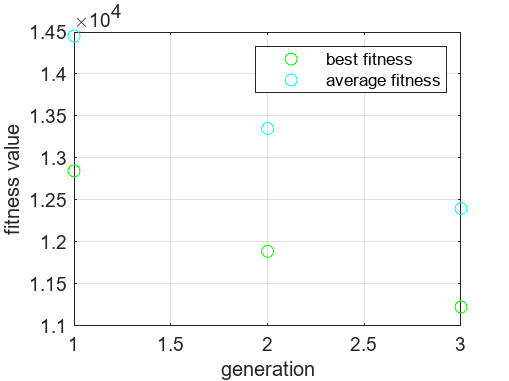

population = 1×3 cell array
    {1×10 cell}    {1×10 cell}    {1×10 cell}


bestFitness = 1.0e+04 *

    1.2848    1.1889    1.1227


avgFitness = 1.0e+04 *

    1.4453    1.3351    1.2398


bestIndividual = 1×3 cell array
    {1×1 cell}    {1×1 cell}    {1×1 cell}


aed = 1×3 cell array
    {1×10 cell}    {1×10 cell}    {1×10 cell}


fitness = 1×3 cell array
    {[1.3725e+04 1.3318e+04 1.4809e+04 1.4756e+04 1.5012e+04 1.4757e+04 1.2848e+04 1.5185e+04 1.5088e+04 1.5031e+04]}    {[1.1889e+04 1.4473e+04 1.3879e+04 1.2394e+04 1.2145e+04 1.2900e+04 1.4465e+04 1.5031e+04 1.1889e+04 1.4441e+04]}    {[1.2522e+04 1.2522e+04 1.4110e+04 1.1799e+04 1.2522e+04 1.2522e+04 1.1227e+04 1.2431e+04 1.1799e+04 1.2522e+04]}



[population,bestFitness,avgFitness,bestIndividual,aed,fitness] = GA_HPO_AED(XOpti, optiSettings) 

This is only an example of how to use the toolbox not an actual optimization to find the best-fitting hyperparameters for the problem.

From the literature is known that genetic algorithms converge exponentially. This means, that when your average fitness is not falling exponentially, you may not have found the right architecture for the problem, or the search space could not be explored well enough. It could help to investigate the search space exploration or increase the number of individuals and or the number of generations as well as investigating and possibly adjusting the ranges of the optimized variables. 

## Train an autoencoder with the HPO results

The goal of performing a hyperparameter optimization is to find a good fitting set of hyperparameters for the problem on hand. 

After performing the HPO one can take the winning individual of the last generation and train an autoencoder on that.

The resulting hyperparameters are stored in the same sequence as the optimizable variables in the struct optimizableVariables.

bestIndividualLast=bestIndividual{length(bestIndividual)}{1}

bestIndividualLast = 1×7 cell array
    {[55]}    {[7973]}    {[10]}    {[10]}    {[3]}    {[10]}    {[29]}


Create a hyperparameter-struct for the AutoencoderDeep based on these optimized hyperparameters:

More information on customizing hyperparameters for the framework AutoencoderDeep can be found in the supplementary documents of the framework "Generic Deep Autoencoders for Time-Series" especially in Example2_AutoencoderDeepWaveforms_customHyperparameterSetting

hpObj=individual2HyperparametersAED(optiSettings,bestIndividualLast)

hpObj =   HyperparametersAED with properties:

    Hyperparameters: [1×1 struct]


Display the newly cretaed hyperparameter struct - the parameters associated with the data, e.g. the number of featuers `NumberFeature `is not set yet, since the newly creted autoencoder hpObj was not trained yet.


hpObj.Hyperparameters

hpObj =   HyperparametersAED with properties:

    Hyperparameters: [1×1 struct]


Train the autoencoder on the hyperparameter struct `hpObj` and the training data `xTrain`

aeTrained=trainAutoencoderDeep(XTrain,hpObj)

ans = struct with fields:
           AutoencoderType: 'VAE'
             LayersEncoder: {'FC'  'LSTM'}
             LayersDecoder: {'Bi-LSTM'}
            NeuronsEncoder: [3 10]
            NeuronsDecoder: 10
                 LatentDim: 2
               NumberEpoch: 29
             NumberFeature: 1
              LearningRate: 7.9730e-04
             MiniBatchSize: 10
      ExecutionEnvironment: 'auto'
               WeightingKL: 55
    OutputTransferFunction: 'none'


show the hyperparameters of the trained autoencoder

aeTrained.Hyperparameters.Hyperparameters

aeTrained =   AutoencoderDeep with properties:

            Version: '3.0.0'
        Description: {'This object was created with the class AutoencoderDeep. This is an object-oriented implementation of autoencoders which can consist out of fully-connected, LSTMand Bi-LSTM layers.'}
            Trained: 1
    Hyperparameters: [1×1 HyperparametersAED]


ans = struct with fields:
           AutoencoderType: 'VAE'
             LayersEncoder: {'FC'  'LSTM'}
             LayersDecoder: {'Bi-LSTM'}
            NeuronsEncoder: [3 10]
            NeuronsDecoder: 10
                 LatentDim: 2
               NumberEpoch: 29
             NumberFeature: 3
              LearningRate: 7.9730e-04
             MiniBatchSize: 10
      ExecutionEnvironment: 'auto'
               WeightingKL: 55
    OutputTransferFunction: 'none'


This trained autoencoder could now be used to analyse data, i.e. performing anomaly detection.

For more information how to apply train autoencoders on data consult the supplimentary documentary of the folder `AutoencoderDeep`.